#  Vectors 

A *vector *is an ordered  list of numbers.  The *size *(also called *dimension *or *length*) of the vector is the number of elements it contains.

vector = [1 3 2]

vector =      1     3     2



vector_size = length(vector)

vector_size = 3

**Zero vectors. **A *zero vector *is a vector with all elements equal to zero.

zero_vector = zeros(1,10);

**Unit vectors. **A *unit vector *is a vector with all elements equal to zero, except one element which is equal to one.

unit_vector1 = [0 0 0 1]

unit_vector1 =      0     0     0     1


unit_vector2 = [0 1 0 0]

unit_vector2 =      0     1     0     0


**Ones vector. **Is a vectro with all its elements equal to one.

ones_vector = ones(1,10)

ones_vector =      1     1     1     1     1     1     1     1     1     1


**Sparsity. **A vector is said to be *sparse *if many of its entries are zero; its *sparsity pattern  *is the set of indices of nonzero entries.  

In MATLAB, sparse vectors (and matrices) are used to efficiently store and manipulate large arrays that contain a significant number of zeros. This is particularly useful in applications where dealing with large-scale data with many zero elements is common.

full_vec = [0, 0, 3, 0, 4, 0, 0]

full_vec =      0     0     3     0     4     0     0


sparse_vec = sparse(full_vec)

sparse_vec =    (1,3)        3
   (1,5)        4


# **Vector addition**

Two vectors *of the same size *can be added together by adding the corresponding elements, to form another vector of the same size, called the *sum *of the vectors  

vector1 = [1, 2, 3]

vector1 =      1     2     3


vector2 = [4, 5, 6]

vector2 =      4     5     6


resultVector = vector1 + vector2;

**Geometric representation**

% Define the vectors
vec1 = [4, 5]

vec1 =      4     5


vec2 = [1, -2]

vec2 =      1    -2



% Calculate the resultant vector
R = vec1 + vec2

R =      5     3


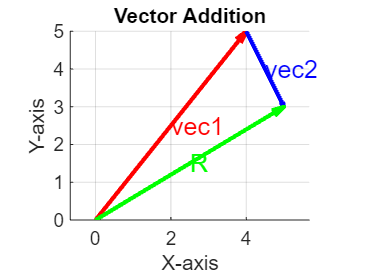


% Create a figure
figure
hold on
grid on
axis equal

% Plot vector A (red)
quiver(0, 0, vec1(1), vec1(2), 1, 'r', 'LineWidth', 2)

% Plot vector B (blue), starting from the head of A
quiver(vec1(1), vec1(2), vec2(1), vec2(2), 1, 'b', 'LineWidth', 2)

% Plot the resultant vector R (green)
quiver(0, 0, R(1), R(2), 1, 'g', 'LineWidth', 2)

% Label the vectors
text(vec1(1)/2, vec1(2)/2, 'vec1', 'FontSize', 12, 'Color', 'r')
text(vec1(1) + vec2(1)/2, vec1(2) + vec2(2)/2, 'vec2', 'FontSize', 12, 'Color', 'b')
text(R(1)/2, R(2)/2, 'R', 'FontSize', 12, 'Color', 'g')

% Add title and labels
title('Vector Addition')
xlabel('X-axis')
ylabel('Y-axis')

# **Scalar-vector multiplication**

Another operation is *scalar multiplication *or *scalar-vector multiplication*, in which a vector is multiplied by a scalar ( *i.e.*, number), which is done by multiplying every element of the vector by the scalar.

# **Linear combinations.**

 If ***a****1, . . . ,****a****m *are *n*-vectors, and ***β***1, . . .* ,****β****m *are scalars, the *n*-vector

                                                        ***β***1***a***1 + *· · · *+ ***β****m****a****m*

is called a *linear combination *of the vectors ***a***1, . . . ,***a****n*.   

# **Inner product**  

The *inner product *(also called *dot product*) of two *n*-vectors is defined as the scalar, sum of the products of corresponding entries.

Examples:

**examples.**

*• ****Unit vector.*** The inner product of a vector with the *i*th standard unit vector gives (or ‘picks out’) the 

*i*th element *a*.

*• ****Sum. ***The inner product of a vector with the vector of ones gives the sum of the elements of the vector.

*•**** Average.***  The inner product of an *n*-vector with the vector  **1/***n *gives the average or mean of the elements of the vector. 

*• ****Sum of squares.***  The inner product of a vector with itself gives the sum of the squares of the elements of the vector.

*• ****Selective sum. ***Let *b *be a vector all of whose entries are either 0 or 1. Then the inner product of b and a is the sum of the elements in *a *for which *b**i *= 1  